# RSA Encryption/Decryption of Multimedia

*EEE8119*

*Chris Hemingway, Yaw Mensah, Paul Wattanajung, Zheliang Geng, Ziaotian Han*

In this demonstration, we encrypt an image with RSA using both Electronic CodeBook (ECB) and Cipher Block Chaining (CBC) encryption.

### Pre-Requisites

Clear variables and command window. 

clc; clear;

Import a demo image. Use MATLAB built-in.

We are using a black and white image, of size 256x256. Printout to verify.

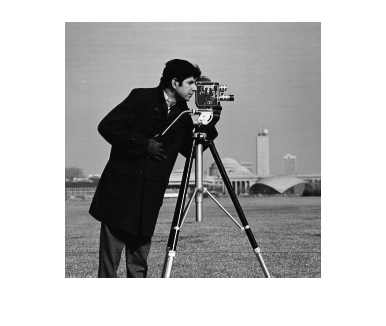

img = imread("cameraman.tif");
    imshow(img);

disp(size(img)); %Get dimensions of image

   256   256



Our RSA library requires the VariablePrecisionInteger library from John D'Errico. This allows us to use integers of length limited only by available memory.

Add this to our path.

addpath(['VariablePrecisionIntegers' filesep 'VariablePrecisionIntegers']);

This is used as the maximum value of an integer that can be precisely represented by MATLAB is $2^{64} -1$for uint64 (64 bit unsigned int), and $2^{52} -1$ for double precision floating point, which is used by default.

intmax('uint64')

ans = uint64
18446744073709551615

This is only 8 (or for double, 7 and a bit) bytes, not enough to encrypt any reasonable message

### Generate Primes

We need two prime numbers $p$ and $q$ to generate our keys.

Requirements are that they are of slightly different lengths, and that the product $n=p\times q$is exactly n_bits in length. 

We wrote a function rsa_find_primes to do this, which given a number of bits, returns two suitable primes. Note these are chosen at random, so the same number of bits may return different primes.

Our function rsa_keygen calls this internally, but let's demonstrate it. Drag the slider to change the number of bits.

[p,q] = rsa_find_primes(22)

p = 1789

q = 2017

fprintf("p is prime? = %s \n", string(isprime(p)));

p is prime? = true 


fprintf("q is prime? = %s \n", string(isprime(q)));

q is prime? = true 


The total number of bits of the product $n=p\times \;q$ is

n=p*q;
fprintf("n=%d \t %s",n,dec2bin(n)); %both in decimal and binary

n=3608413 	 1101110000111101011101

fprintf("n is %d bits",length(dec2bin(n))); %Number of bits

n is 22 bits

## Generate Keys

Once we have our 2 prime numbers, we can generate the keys. This is done in the function rsa_keygen, which we will describe key features of here. Let's call it now, and time how long it takes for later.

[Kp, Ks] = rsa_keygen(48); %48 bit key as example
disp(Kp); disp(Ks);

    n: 2.1302e+14
    e: 5

    n: 2.1302e+14
    d: [1×1 vpi]



Here we refer to the **public** key as $K_p$ and the **private** (secret) key as $K_s$

#### Public/Private Base n

disp (Kp.n);

   2.1302e+14



Our base $n$ is what is used in the modular exponentiation in both encryption and decryption, and is part of the public and private keys. It's definition is simple.

Note that the width of n in bits is commonly referred to as the **size** of our public/private key. This is a parameter we would like to specify, we chose **32 bits** above, lets check that $n$ is actually this value:

ceil(log2(Kp.n))

ans = 48

The strength of RSA relies on it being slow to factorise $n$ into prime factors. For our simple 32 bit key, this can be done relatively quickly. Let's see how long it takes:

tic;
factor(Kp.n);
toc

Elapsed time is 0.225887 seconds.


On my computer (a 2013 Macbook Air), that took 200ms. Quite slow, considering choosing the primes only took ~10ms, 20x faster. 

For practical uses of RSA such as TLS (used in HTTPS),[ 2048 bit key lengths are recommended](https://github.com/ssllabs/research/wiki/SSL-and-TLS-Deployment-Best-Practices#11-use-2048-bit-private-keys), which are consided impractical to factor in reasonable time.

tic;
rsa_find_primes(48);
toc

Elapsed time is 0.008840 seconds.


#### Public Exponent $e$

We need to choose our  **exponent **$e$as part of the public key.

Define the intermediate value $X=\lambda \left(n\right)$, where $\lambda \;$is [Carmicheal's Totient Function](https://en.wikipedia.org/wiki/Carmichael_function)${\lambda \left(n\right)\;\mathrm{returns}\;m\;\mathrm{where}\;a}^m \;\mathrm{mod}\;n=1$. This is the **maximum** possible value of $e$, and $e$ must also be coprime to $X$.

In determining $X$, we can take advantage of $p$ and $q$ being prime, to use a simplification to the Carmicheal function.

(TODO EXPLANATION)


$$X=\left(p-1\right)\times \left(q-1\right)$$


To speed up encryption, it is beneficial if e is a small number (and has a small hamming weight, which is corellated). Therefore, we use a simple algorithm of testing all values between 3 and $X$ ascending for being coprime with $X$. This is shown below.

#### Private Exponent $d$

The private key exponent $d$ is defined from our public exponent $e$ and secret (never used) variable $X$as


$$d\times e\;\mathrm{mod}\;X=1$$


This operation is known as the **modular multiplicative inverse. **

Calculating this is quite involved, so we utilise a function of the VariablePrecisionInteger library to calculate thi

disp(Ks.d);

    170412032774381


#### Private Key Base

The base of the private key is actually the same as the base of the private key. 

Kp.n == Ks.n %#ok<EQEFF>

ans = logical
   1


However, we include it in the private key as then whatever decrypts does not need to know the private key too.

## Encryption/Decryption

#### Algorithm

Encryption of a message in RSA is performed by the algorithm


$$C=P^e \mathrm{mod}\;n$$


Where $P$ is plaintext, $C$is the ciphertext, $e$is the public exponent, and $n$is the public base.

We implement this in the function rsa_encrypt.m

#### Text Encryption

For a short message, the length is less than the key length

plaintext = 'hello';
key_bits= ceil(log2(Kp.n))

key_bits = 48

plaintext_bits = length(plaintext)*8

plaintext_bits = 40

ciphertext = rsa_encrypt('hello',Kp)

ciphertext =
    34048730172025


Decryption is also easy

decrypted = rsa_decrypt(ciphertext,Ks)

decrypted = 'hello'

However, look what happens when our message is greater than the key length.

plaintext = 'A longer message';
plaintext_bits = length(plaintext)*8

plaintext_bits = 128

ciphertext = rsa_encrypt(plaintext,Kp);
decrypted = rsa_decrypt(ciphertext, Ks);
disp(decrypted);

B¨¾	Õ


Our message has been corrupted! This is because $\mathrm{if}\;y>n,\;y\;\mathrm{mod}\;n\;\not= y$, and therefore the modulus operation has "truncated" our message.

#### Image Size

For our image, the size is much larger than our key length.


$$\mathrm{bits}=\mathrm{width}\times \mathrm{height}\times \mathrm{bits}_\mathrm{per}_\mathrm{pixel}$$


max_pixel_value = double(intmax(class(img)));
bits_per_pixel = ceil(log2(max_pixel_value))

bits_per_pixel = 8

image_bits = numel(img)*bits_per_pixel

image_bits = 524288

disp(key_bits);

    48



Therefore, we need a different approach.